# Derivation of state equation for thermal network

close all;
clear;
clc;

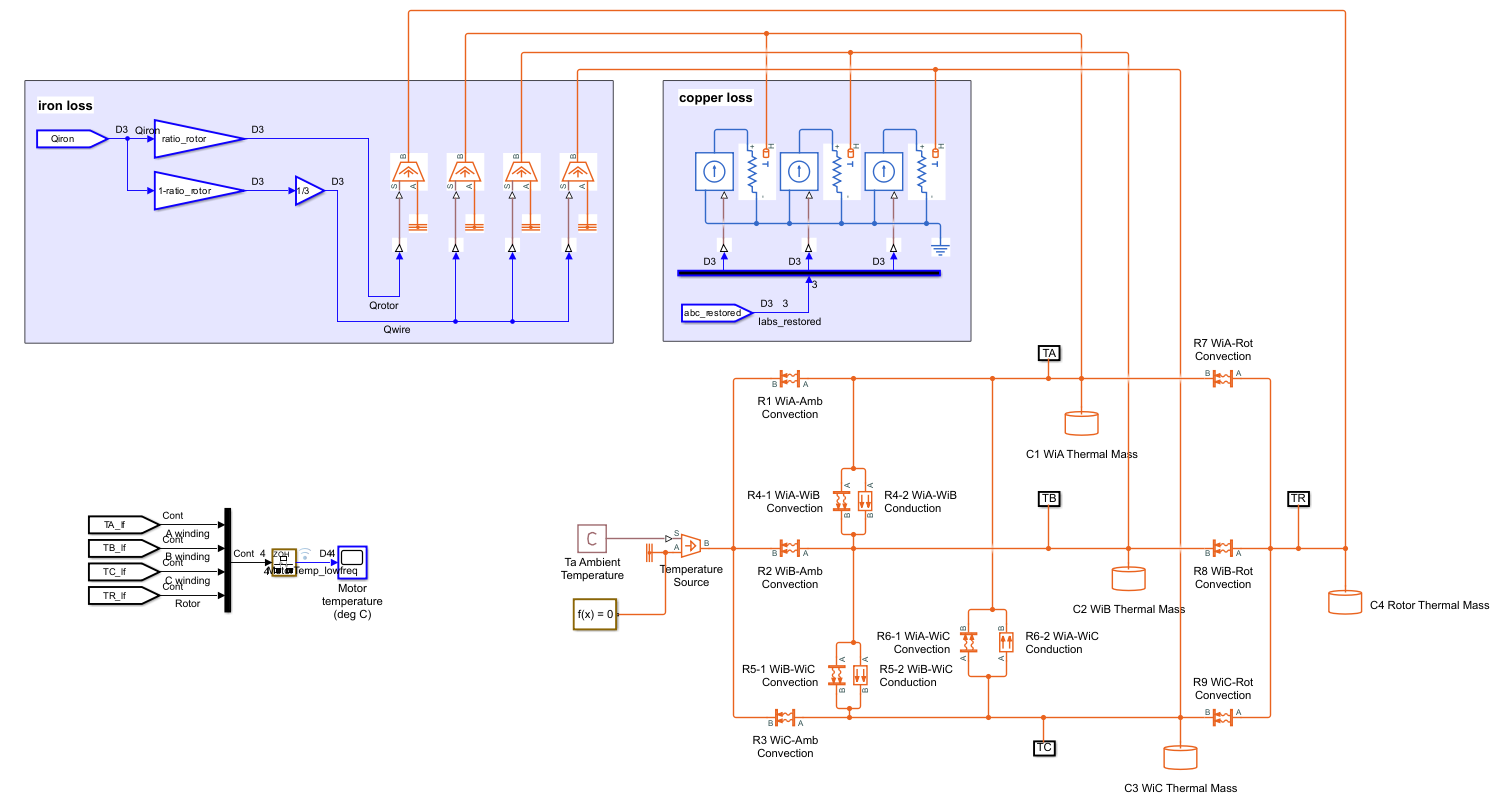

## define variables

### state

$x_1$ wire A temperature $T_A \mathrm{[K]}$

$x_2$ wire B temperature $T_B \mathrm{[K]}$

$x_3$ wire C temperature $T_C \mathrm{[K]}$

$x_4$ rotor temperature $T_R \mathrm{[K]}$

### input

$u_1$ wire A current $I_A \mathrm{[A]}$

$u_2$ wire B current $I_B \mathrm{[A]}$

$u_3$ wire C current $I_C \mathrm{[A]}$

$u_4$ ambient temperature $T_a \mathrm{[K]}$

$u_5$ iron loss $Q_{iron} \mathrm{[W]}$

% states
syms x [4,1] real
T_A = x(1);
T_B = x(2);
T_C = x(3);
T_R = x(4);

% inputs
syms u [5,1] real
I_A = u(1);
I_B = u(2);
I_C = u(3);
T_a = u(4);
Q_iron = u(5);

% params
syms R [9,1] real
syms C [4,1] real
syms T_0 real
syms R_0 real
syms alpha real
syms ratio_rotor real

## heat flux

### copper loss

Q_copper_A = I_A^2*R_0*(1+alpha*(T_A-T_0));
Q_copper_B = I_B^2*R_0*(1+alpha*(T_B-T_0));
Q_copper_C = I_C^2*R_0*(1+alpha*(T_C-T_0));

### iron loss

#### wire

Q_iron_wire = Q_iron*(1-ratio_rotor);
Q_iron_A = Q_iron_wire/3;
Q_iron_B = Q_iron_wire/3;
Q_iron_C = Q_iron_wire/3;

#### rotor

Q_iron_rotor = Q_iron*ratio_rotor;

### through thermal resistance

#### wire to environment

q(1) = (T_A-T_a)/R(1);
q(2) = (T_B-T_a)/R(2);
q(3) = (T_C-T_a)/R(3);

#### wire to wire

q(4) = (T_A-T_B)/R(4);
q(5) = (T_B-T_C)/R(5);
q(6) = (T_C-T_A)/R(6);

#### rotor to wire

q(7) = (T_R-T_A)/R(7);
q(8) = (T_R-T_B)/R(8);
q(9) = (T_R-T_C)/R(9);

## time derivative of temperature

#### state equation

f(1) = (Q_copper_A+Q_iron_A-q(1)-q(4)+q(6)+q(7))/C(1);
f(2) = (Q_copper_B+Q_iron_B-q(2)-q(5)+q(4)+q(8))/C(2);
f(3) = (Q_copper_C+Q_iron_C-q(3)-q(6)+q(5)+q(9))/C(3);
f(4) = (Q_iron_rotor-q(7)-q(8)-q(9))/C(4);

f = f.'

$$f = \begin{array}{l} \left(\begin{array}{c} -\frac{\sigma_{1}-\frac{u_{4}-x_{1}}{R_{1}}+\frac{x_{1}-x_{2}}{R_{4}}+\frac{x_{1}-x_{3}}{R_{6}}+\frac{x_{1}-x_{4}}{R_{7}}+R_{0}\,{u_{1}}^{2}\,\left(\alpha \,\left(T_{0}-x_{1}\right)-1\right)}{C_{1}}\\ -\frac{\sigma_{1}-\frac{u_{4}-x_{2}}{R_{2}}-\frac{x_{1}-x_{2}}{R_{4}}+\frac{x_{2}-x_{3}}{R_{5}}+\frac{x_{2}-x_{4}}{R_{8}}+R_{0}\,{u_{2}}^{2}\,\left(\alpha \,\left(T_{0}-x_{2}\right)-1\right)}{C_{2}}\\ -\frac{\sigma_{1}-\frac{u_{4}-x_{3}}{R_{3}}-\frac{x_{2}-x_{3}}{R_{5}}-\frac{x_{1}-x_{3}}{R_{6}}+\frac{x_{3}-x_{4}}{R_{9}}+R_{0}\,{u_{3}}^{2}\,\left(\alpha \,\left(T_{0}-x_{3}\right)-1\right)}{C_{3}}\\ \frac{{\mathrm{ratio}}_{\mathrm{rotor}}\,u_{5}+\frac{x_{1}-x_{4}}{R_{7}}+\frac{x_{2}-x_{4}}{R_{8}}+\frac{x_{3}-x_{4}}{R_{9}}}{C_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{u_{5}\,\left({\mathrm{ratio}}_{\mathrm{rotor}}-1\right)}{3} \end{array}$$

#### output equation

h(1) = T_R;

h = h.'

$$h = x_{4}$$

## substitute parameters

controller_parameters();
f = subs(f,C,C_);
f = subs(f,R,R_);
f = subs(f,[T_0,R_0,alpha], [T_0_,R_0_,alpha_]);
f = subs(f,ratio_rotor,ratio_rotor_);
f

$$f = \left(\begin{array}{c} \frac{u_{4}}{50}+\frac{u_{5}}{1200}-\frac{27\,x_{1}}{250}+\frac{3\,x_{2}}{125}+\frac{3\,x_{3}}{125}+\frac{x_{4}}{25}+\frac{13\,{u_{1}}^{2}\,\left(\frac{393\,x_{1}}{100000}-\frac{343459}{2000000}\right)}{100000}\\ \frac{u_{4}}{50}+\frac{u_{5}}{1200}+\frac{3\,x_{1}}{125}-\frac{27\,x_{2}}{250}+\frac{3\,x_{3}}{125}+\frac{x_{4}}{25}+\frac{13\,{u_{2}}^{2}\,\left(\frac{393\,x_{2}}{100000}-\frac{343459}{2000000}\right)}{100000}\\ \frac{u_{4}}{50}+\frac{u_{5}}{1200}+\frac{3\,x_{1}}{125}+\frac{3\,x_{2}}{125}-\frac{27\,x_{3}}{250}+\frac{x_{4}}{25}+\frac{13\,{u_{3}}^{2}\,\left(\frac{393\,x_{3}}{100000}-\frac{343459}{2000000}\right)}{100000}\\ \frac{3\,u_{5}}{800}+\frac{x_{1}}{50}+\frac{x_{2}}{50}+\frac{x_{3}}{50}-\frac{3\,x_{4}}{50} \end{array}\right)$$

### export to file

matlabFunction(f,'File','nonlinear_model/state_equation.m','Vars',{x,u});
matlabFunction(h,'File','nonlinear_model/output_equation.m','Vars',{x});
matlabFunction(x+f*Ts,'File','nonlinear_model/state_equation_discrete.m','Vars',{x,u});

## linearization

### Jacobi matrix

A = jacobian(f,x)

$$A = \left(\begin{array}{cccc} \frac{5109\,{u_{1}}^{2}}{10000000000}-\frac{27}{250} & \frac{3}{125} & \frac{3}{125} & \frac{1}{25}\\ \frac{3}{125} & \frac{5109\,{u_{2}}^{2}}{10000000000}-\frac{27}{250} & \frac{3}{125} & \frac{1}{25}\\ \frac{3}{125} & \frac{3}{125} & \frac{5109\,{u_{3}}^{2}}{10000000000}-\frac{27}{250} & \frac{1}{25}\\ \frac{1}{50} & \frac{1}{50} & \frac{1}{50} & -\frac{3}{50} \end{array}\right)$$

B = jacobian(f,u)

$$B = \left(\begin{array}{ccccc} \frac{13\,u_{1}\,\left(\frac{393\,x_{1}}{100000}-\frac{343459}{2000000}\right)}{50000} & 0 & 0 & \frac{1}{50} & \frac{1}{1200}\\ 0 & \frac{13\,u_{2}\,\left(\frac{393\,x_{2}}{100000}-\frac{343459}{2000000}\right)}{50000} & 0 & \frac{1}{50} & \frac{1}{1200}\\ 0 & 0 & \frac{13\,u_{3}\,\left(\frac{393\,x_{3}}{100000}-\frac{343459}{2000000}\right)}{50000} & \frac{1}{50} & \frac{1}{1200}\\ 0 & 0 & 0 & 0 & \frac{3}{800} \end{array}\right)$$

C = jacobian(h,x)

$$C = \left(\begin{array}{cccc} 0 & 0 & 0 & 1 \end{array}\right)$$

matlabFunction(A,'File','Jacobian/dfdx.m','Vars',{x,u});
matlabFunction(C,'File','Jacobian/dhdx.m','Vars',{x});

### equilibrium point to check observability

xe = [298.15,298.15,298.15,298.15]';
ue = [1.0,2.0,3.0,300,0.0]';

A_lin = double(subs(A,[x;u],[xe;ue]));
B_lin = double(subs(B,[x;u],[xe;ue]));
C_lin = double(subs(C,[x;u],[xe;ue]));

### observability

Go = obsv(A_lin,C_lin);
rank(Go)

ans =      4
